Given Data:

weight = 0.420 * 9.81;
Cd = 0.97;
S = 0.01;
dia = 0.2032

dia = 0.2032

radius = dia/2;
A = pi*radius^2;
no_of_cells = 3;
batt_power = 1500;
density_sea = 1.225;
m_e = 0.75;
esc_e = 0.85;
Eb = no_of_cells * 3.7 * 1500/(1000) * 3600;

Calculation of Range, Endurance & Forward Speed:

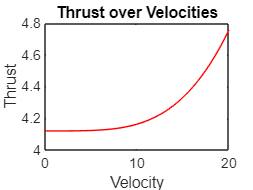

V = 0:0.5:20;

for i = 1:41

    drag(i) = 0.5 * density_sea * S * Cd * V(i)^2;

    thrust(i) = sqrt(weight^2 + drag(i)^2);
    
    alpha_d(i) = atan(drag(i)/weight);

    constant(i) = (weight^2 + drag(i)^2)/(2*density_sea*4*A)^2;

    %%v(i)^4 + (2 * V(i)*sin(alpha_d))*v(i)^3 + V(i)^2*v(i)^2 - constant(i) == 0;

    p = [1, 2 * V(i)*sin(alpha_d(i)), V(i)^2, 0, -constant(i)];
    r = roots(p);
    v(i) = r(real(r)>0 & imag(r) ==0);

    P_total(i) = thrust(i)*(v(i) + V(i)*sin(alpha_d(i)));
    tot_pow_velocity(i) = P_total(i)/V(i);

end

plot(V,thrust, "r");
xlabel("Velocity");
ylabel("Thrust");
title("Thrust over Velocities");

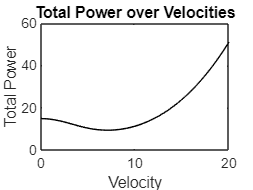



plot(V,P_total,"k");
xlabel("Velocity");
ylabel("Total Power");
title("Total Power over Velocities");

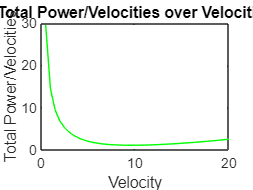



plot(V,tot_pow_velocity,"g");
xlabel("Velocity");
ylabel("Total Power/Velocities");
title("Total Power/Velocities over Velocities");


P_total_min = min(P_total);
Tot_pow_V_min = min(tot_pow_velocity);

k = find(P_total == P_total_min);
k2 = find(tot_pow_velocity == Tot_pow_V_min);

fs_endurance = V(k);
fs_range = V(k2);


max_endurance = (Eb * m_e * esc_e)/(P_total_min * 60) ;

max_range = (Eb * m_e * esc_e)/(Tot_pow_V_min * 1000);


